# Taller de Simulación Numérica

*F. Pena, P. Quintela*

## Tema 6. El método de los elementos finitos 1D

Consideramos el siguiente problema de contorno (P):


$$\left\{\begin{array}{ll}
-(p(x)u(x)')'+q(x)u(x)'+r(x)u(x)=f(x),\\
u(a)=u_a\text{  ó  } -p(a)u'(a)+h_a u(a)= g_a,\\
u(b)=u_b\text{  ó  } \ \ \, p(b)u'(b)+h_b u(b) = g_b.
\end{array}
$$


Aunque usaremos esta notación por ser habitual en el método de los elementos finitos (FEM, en inglés), observa que se podría hacer la equivalencia con la notación de las prácticas anteriores cambiando $(u, p, q, r, f, g_a, g_b)$ por $(y, 1, w, v, -u, u_a, u_b)$. 

Por comodidad, omitimos la dependencia en $x$ y los límites de integración entre $a$ y $b$. La *formulación débil*, o *variacional*, de (P) es:


$$-\int (pu')'v+\int qu'v+\int ruv=\int fv$$


Usamos la identidad de Green $\int (pu'v)' =$ $\int (pu')'v + \int pu'v' = [pu'v]_a^b$  para obtener la formulación que resolveremos con nuestro programa:

$\int pu'v'-[pu'v]_a^b+\int qu'v+\int ruv=\int fv$.

### Existencia y unicidad de solución del problema continuo

Sin pérdida de generalidad, en este apartado analizamos el problema (P) con condición Dirichlet nula en $a$ y Neumann en $b$, es decir, encontrar $u\in\mathcal{C}^2([a,b])$ tal que


$$\left\{\begin{array}{ll}
-(p(x)u(x)')'+q(x)u(x)'+r(x)u(x)=f(x),\\
u(a)=0,\\
p(b)u'(b) = g_b.
\end{array}
$$


En su formulación débil, se trata de encontrar $u\in V,\ u(a) = 0$ tal que


$$\int pu'v'-(pu'v)(b)+\int qu'v+\int ruv=\int fv, \text{ para todo }v\in V,\ v(a) =0.$$


siendo $V=\left\{v:[a,b]\to\mathbb{R}: \int_a^b(v^2 +(v')^2<+\infty\right\}$.

Denotamos $V_0=\left\{v\in V:v(a) = 0\right\}$; el problema anterior es un caso particular del de encontrar $u\in V_0$ tal que


$$a(u,v) = L(v), \text{ para todo }v\in V_0,$$


siendo $a:V\times V\to\mathbb{R}$ bilineal y $L:V\to\mathbb{R}$ lineal.

#### Espacio de Sobolev

En la biliografía, V se suele denominar *espacio de Sobolev* $H^1(a,b)$, dotado del producto escalar $(u,v) =\int uv+u'v'$ y de la norma $\|u\|_V= \left(\int u^2+(u')^2\right)^{\frac{1}{2}}$.

Análogamente, se denota por $H^1_0(a,b)$ a $V_0$.

#### Teorema de Lax-Milgram

Considera las siguientes definiciones:

1. Se dice que $a$* es continua sobre *$V\times V$ si existe una constante $M>0$ tal que:$|a(u,v)| \leq M\|u\|_V\|v\|_V, \text{ para todo }u,v\in V.$

Es cierto en nuestro caso, pues $\left|\int pu'v+\int qu'v+\int ruv\right| \leq M\|u\|_V\|v\|_V

$ por la continuidad de $p,\ q\text{ y } r$.

2. Se dice que $L$* es continuo sobre *$V$ si existe una constante $M_L>0$ tal que:


$$|L(v)| \leq M_L\|v\|_V, \text{ para todo }v\in V.$$


Es cierto en nuestro caso, pues $\left|\int fv+u_bv(b)\right|\leq M_L\|v\|_V

$ por la continuidad de $f$, la desigualdad de Hölder y la inyección continua de $H^1(a,b)$ en $\mathcal{C}^0([a,b])$.

3. Se dice que $a$* es *$V_0$*-coerciva* si existe una constante $\alpha>0$ tal que:


$$|a(v,v)| \geq \alpha \|v\|^2_V, \text{ para todo }v\in V_0.$$


Es cierto en nuestro caso, por la *desigualdad de Poincaré* en $V_0$, que afirma que existen dos constantes $M_1, M_2>0$, tales que:

 $M_1\|v\|_V^2\leq \int (v')^2 \leq M_2\|v\|_V^2,\text{ para todo }v\in V_0$.

Finalmente, el teorema de Lax-Milgram afirma que:

*Si *$a$* es una forma bilineal continua sobre *$V\times V$* y *$V_0$*-coerciva, y *$L$* es una forma continua sobre *$V$*, entonces el problema de encontrar *$u\in V_0$* tal que *$a(u,v) = L(v) \text{ para todo }v\in V_0$* admite una solución única.*

### Problema discreto

Los métodos de los elementos finitos aproximan el problema variacional anterior por un problema con un número finito de incógnitas o *grados de libertad*. El método de Galerkin reemplaza $V$ por subespacios de dimensión finita $V_h\subset V$, con $\text{dim}\,(V_h)=N_h$, $\lim_{h\to 0}N_h=+\infty$, y define el problema discretizado (Ph):

Hallar $u_h\in V_{h,0}$ tal que:


$$a(u_h, v_h) = L(v_ h),\text{ para todo }v_h\in V_{h,0}$$


Dada una base $\{\omega_i\}_{i=1}^{N_h}$de $V_h$, la base de $V_{h,0}$ es un subconjunto de la anterior. La solución $u_h(x) = \sum_{i=1}^{N_h}u^i_h\omega_i(x)$se puede identificar con el vector $\mathbf{u}_h = (u_h^i)$y el problema discreto puede escribirse como:

$\mathbf{v}_h^tA_h\mathbf{u}_h = \mathbf{v}_h^t\mathbf{b}_h$,

donde $(A_h)_{i j}=a(\omega_j,\omega_i)$, $\mathbf{b}_{h,i} = L(\omega_i)$, $v_h(x) = \sum_{j=1}^{N_h}v^j_h\,\omega_j(x)$ y $\mathbf{v}_h = (v_h^j)$

Para evitar que $A_h$ sea llena se escogen bases $V_h$ con funciones de soporte "reducido". 

#### Mallado del dominio

Pondremos entre paréntesis los términos equivalentes en prácticas anteriores. Tomamos una *malla* (partición) de $[a,b]$ con:

- *elementos* (subintervalos) $T_k=[x_k, x_{k+1}],\ k=1,\ldots, N_{el}$,

- *vértices* (extremos)  $a=x_1<x_2<\ldots < x_{N_{ver}}=b$, siendo $N_{ver} = N_{el}+1$,

- *longitudes* (paso variable) $h_k=x_{k+1}-x_k],\ k=1,\ldots, N_{el}$,

- *parámetro de la malla* (longitud máxima) $h= \max_{1\leq k \leq N_{el}} h_k$. 

### Elementos finitos de Lagrange lineales

En los elementos finitos de Lagrange, los grados de libertad son el valor de la función en los *nodos* de la malla. En el caso lineal, los nodos coinciden con los vértices:

- nodos $n_i = x_i,\ i=1,\ldots,N_{nod},\ N_{nod}=N_{ver}$.

En este caso, el espacio discreto se define como:


$$V_h=\left\{v\in\mathcal{C }^0([a,b]):\  \left.v\right|_{T_k}\in\mathcal{P}^1,\ k=1,\ldots,N_{el}\right\}$$


siendo $\mathcal{P}^1$ el espacio de polinomios de grado 1. La base de $V_h$ escogida verifica:


$$\omega_i(n_j) = \delta_{ij},\ i,j=1,\ldots,N_{nod}$$


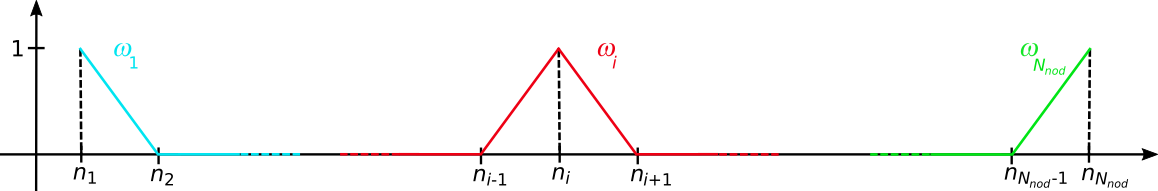

#### Orden de convergencia

Sea $H^2(a,b)=\left\{v\in L^2(a,b):\ v',v''\in L^2(a,b)\right\}$ con norma $\|v\|_{H^2} = \left(\|v\|_{L^2}+\|v'\|_{L^2}+\|v''\|_{L^2}\right)^{\frac{1}{2}}$. Si $u\in H^2(a,b)$ es solución de (P), entonces la solución $u_h$ de  (Ph) con elementos finitos de Lagrange lineales verifica:


$$\|u^{(l)}- u_h^{(l)}\|_{L^2} \leq \mathcal(O)(h^{2-l}),\ l\in\{0,1\}.$$


### Construcción del sistema discreto

El cálculo de las integrales de $a(\omega_j,\omega_i)$ y $L(\omega_i)$ en todo $[a,b]$ es ineficiente, porque se calculan las mismas integrales repetidamente. El método que se usa en la práctica realiza los cálculos elemento por elemento. Denotamos por $x^k_1, x^k_2$ los extremos del $T_k = [x_k, x_{k+1}]$. Las funciones de $V_h|_{T_k}$ son combinaciones de los polinomios lineales que cumplen $P^k_i(x^k_j) = \delta_{i,j},\ i,j\in\{1,2\}$.

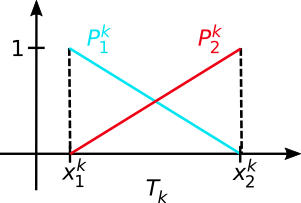

Por tanto, para cada $v_h\in V_h$,


$$v_h(x)|_{T_k} = \sum_{i=1}^{2}v_h(x_i^k)P^k_i(x) = [P^k_1(x) P^k_2(x)] \left(\begin{array}{c}v_h(x_1^k) \\ v_h(x_2^k)\end{array}\right) = [P^k](x) (\mathbf{v}_h)_k,$$


y su derivada es


$$v'_h(x)|_{T_k} = [(P^k_1)'(x) (P^k_2)'(x)] \left(\begin{array}{c}v_h(x_1^k) \\ v_h(x_2^k)\end{array}\right) = [DP^k](x) (\mathbf{v}_h)_k.$$


La matriz del problema dicreto $(P_h)$ puede escribirse como suma de integrales por elemento. Por ejemplo:

$\int_a^b pu_h'v_h' = \sum_{k=1}^{N_{el}}\int_{T_k}(pu_h'v'_h)|_{T_k} = \sum_{k=1}^{N_{el}}(\mathbf{v}_h)^t_k\left(\int_{T_k}[DP^k]^tp|_{T_k}[DP^k]\right)(\mathbf{u}_h)_k$.

Si definimos para elemento $T_k$ la *matriz elemental* $[A_h^k]\in\mathcal{M}_{2\times 2}(\mathbb{R})$,

$[A_h^k] = \int_{T_k}[DP^k]^tp|_{T_k}[DP^k] + \int_{T_k}[P^k]^tq|_{T_k}[DP^k] + \int_{T_k}[P^k]^tr|_{T_k}[P^k]$,

entonces, salvo los términos frontera que veremos cómo implementar más adelante, 

$a(u_h,v_h) =  \sum_{k=1}^{N_{el}}(\mathbf{v}_h)^t_k[A_h^k](\mathbf{u}_h)_k$.

Del mismo modo, 

podemos definir el *segundo miembro elemental* $\mathbf{b}_h^k\in\mathbb{R}^2$,

$\mathbf{b}_h^k = \int_{T_k}[P^k]^tf|_{T_k}$,

y escribir

$L(v_h) =  \sum_{k=1}^{N_{el}}(\mathbf{v}_h)^t_k\mathbf{b}_h^k$.

#### Ensamblado de los términos elementales

El paso del sistema elemental $2\times 2$ al global $N_{nod}\times N_{nod}$ se hace con las matrices de ensamblado $B_k\in\mathcal{M}_{2\times N_{nod}}(\mathbb{R})$,


$$[B^k]_{i,j} = \left\{\begin{array}{ll}
1& \text{ si } x_j = x^k_i, \\ 
0 & \text{ en otro caso.}\end{array}\right.$$


Por ejemplo, para el elemento $T_k = [x_{2}, x_{3}]$, los elementos $B_{1,2}$ y $B_{2,3}$ valen 1 y el resto son nulos. De este modo, 

$A_h + [B^k]^t[A_h^k][B^k]$ añadiría $[A_h^k]$ en las posiciones $[2,3]\times [2,3]$ de $A_h$. El número total de elementos no nulos de $A_h$ es $3N_{nod}-2$. En la siguiente figura, podemos ver el perfil de $A_h$ con elementos lineales, $N_{el}=4$, $N_{ver}=N_{nod} = 5$.

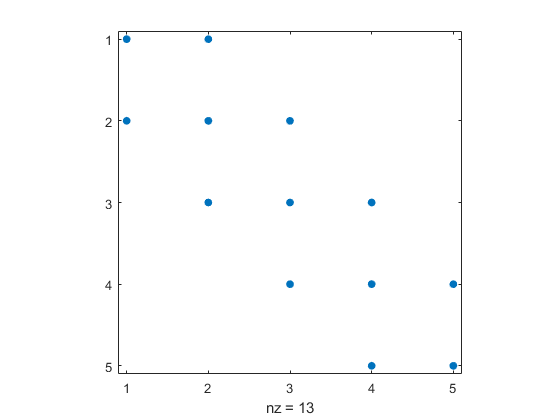

De este modo, podemos escribir que

$A_h = \sum_{k=1}^{N_{el}} [B^k]^t[A_h^k][B^k]$, $\mathbf{b}_h = \sum_{k=1}^{N_{el}}[B^k]^t\mathbf{b}_h^k$.

La matriz del problema discreto es una matriz banda con ancho 2, es decir, $(A_h)_{i j}=0$ si $|i-j|\geq 2$. En particular, es una matriz *dispersa* (con gran parte de elementos nulos) y el problema puede resolverse de forma más rápida que de haber tenido una matriz *llena*.

#### Cálculo de los términos elementales

Las integrales elementales se calculan cambiando a un elemento de referencia $\hat{T} = [0,1]}$. Para $\hat{x}\in \hat{T}$, los elementos de la base local son

$[\hat{P}] = [1-\hat{x},\ \hat{x}]$,

$[\hat{D}\hat{P}] = [-1, 1]$.

La aplicación afín $F_k: \hat{x}\in\hat{T} \to x\in T_k$definida por $F_k(\hat{x}) = (x_2^k-x_1^k)\hat{x}+x_1^k$ permite cambiar a la variable del elemento de referencia. Se tiene que:

$[P^k]\circ F_k  = [\hat{P}]$.

Además, por la regla de la cadena, 


$$\frac{\mathrm{d}}{\mathrm{d}\hat{x}} \left(P_i^k\circ F_k\right)(\hat{x}) = 

\frac{\mathrm{d}}{\mathrm{d}x} P_i^k (F_k(\hat{x})) \frac{\mathrm{d}}{\mathrm{d}\hat{x}} F_k(\hat{x}) = 

h_k \frac{\mathrm{d}}{\mathrm{d}x} P_i^k (F_k(\hat{x})). $$


En notación matricial,

$[DP^k] \circ F_k = \frac{1}{h_k}[\hat{D}\hat{P}]$.

Por la fómula de cambio de variable, dada una función $g$ a integrar en $T_k$,

$\int_{T_k} g(x)\,\mathrm{d}x = \int_{\hat{T}} g(F_k(\hat{x}))\,h_k\,\mathrm{d}\hat{x}$.

De este modo, podemos reescribir la matriz y el segundo miembro elementales:

$[A_h^k] = \frac{1}{h_k}\int_{\hat{T}}[\hat{D}\hat{P}]^t(p\circ F_k)[\hat{D}\hat{P}] + \int_{\hat{T}}[\hat{P}]^t(q\circ F_k)[\hat{D}\hat{P}] + h_k\int_{\hat{T}}[\hat{P}]^t (r\circ F_k)[\hat{P}]$,

$\mathbf{b}_h^k = h_k\int_{\hat{T}}[\hat{P}]^t(f\circ F_k)$.

#### Integración numérica

Se deben usar fórmulas de integración numérica para calcular las integrales en el elemento de referencia. Por ejemplo,

- Cuadratura gaussiana de 1 punto o fórmula de Poncelet:  $\int_0^1f \approx f(0.5)$, exacta para $\mathcal{P}^1$.

- Formula del trapecio: $\int_0^1f \approx \frac{1}{2}\left(f(0)+f(1)\right)$, exacta para $\mathcal{P}^1$.

- Cuadratura gaussiana de 2 puntos: $\int_0^1f \approx \frac{1}{2}\left(f(\frac{1-1/\sqrt{3}}{2})+f(\frac{1+1/\sqrt{3}}{2})\right)$, exacta para $\mathcal{P}^3$.

En general, se usa la fórmula de cuadratura que integra el término de forma exacta las funciones $p$, $q$, $r$ y $f$están en $V_h$. Recuerda que la cuadratura gaussiana de $n$ puntos es exacta en $\mathcal{P}^{2n-1}$. Véase, por ejemplo, [O.C. Zienkiewicz and R.L. Taylor. The Finite element method. Volumen 1. Butterworth-Heinemann, 2000](https://iacobus.usc.es/record=b1734436~S1*gag). 

#### Condiciones Neumann y Robin

Recordamos que las condiciones Robin (y Neumann como caso particular) son:


$$\left\{\begin{array}{ll}
-p(a)u'(a) +h_a u_a = g_a,\\
\ p(b)u'(b) +h_b u_b = g_b.
\end{array}
$$


En la formulación débil aparece el término $-[pu'v]_a^b$. Al sustiruir la expresión de las condiciones se obtiene:

- $h_au(a)v(a) + h_bu(b)v(b)$ en el lado izquierdo de la ecuación,

- $g_av(a) + g_bv(b)$ en el lado derecho.

En el problema discreto se traduce en que debemos ensamblar (añadir):

- $h_a$ y $h_b$ en $(A_h)_{11}$ y $(A_h)_{N_{nod}\,N_{nod}}$, respectivamente,

- $g_a$ y $g_b$ en $\mathbf{b}_{h,1}$ y $\mathbf{b}_{h,N_{nod}}$, respectivamente.

#### Bloqueo de condiciones Dirichlet

Recordamos que las condiciones Dirichlet son:


$$\left\{\begin{array}{l}
u(a)=u_a,\\
u(b)=u_b.
\end{array}
$$


**Bloqueo por sustitución**

Al igual en `df`, se pueden sustituir las filas del sistema correspondientes a las incógnitas con condición Dirichlet por una ecuación que devuelva la solución prescrita:


$$\left\{\begin{array}{lllll}
(A_h)_{1j} &= 0, &j=2,\ldots,N_{nod}, & \mathbf{b}_1 &= (A_h)_{11}\,u_a,\\
(A_h)_{N_{nod}\,j} &= 0, &j=1,\ldots,N_{nod}-1, & \mathbf{b}_{N_{nod}} &= (A_h)_{N_{nod}\, N_{nod}}\,u_b.
\end{array}\right.$$


La razón para mantener el valor de la matriz en la diagonal es no modificar el tamaño de los elementos diagonales para evitar empeorar su número de condición.

**Bloqueo por pivote**

A pesar de la precaución, el modificar sólo el elemento diagonal tiene la ventaja reducir el número de elementos a cambiar:


$$\left\{\begin{array}{llll}
(A_h)_{11} &= 10^{30}, & \mathbf{b}_1 &= 10^{30}\,u_a,\\
(A_h)_{N_{nod}\,N_{nod}} &= 10^{30}, & \mathbf{b}_{N_{nod}} &= 10^{30}\,u_b.
\end{array}\right.$$


**Bloqueo por condensación**

Al igual en `dfd`, se pueden eliminar del sistema las filas correspondientes a las incógnitas con condición Dirichlet:

- Eliminar la primera fila y columna del sistema, y $\mathbf{b}_{h,i} = \mathbf{b}_{h,i} - (A_h)_{i1}\,u_a,\ i=2,\ldots,N_{nod}$,

- Eliminar la última fila y columna del sistema y $\mathbf{b}_{h,i} = \mathbf{b}_{h,i} - (A_h)_{i\,N_{nod}}\,u_b,\ i=1,\ldots,N_{nod}-1$.

### Elementos finitos de Lagrange cuadráticos

En este caso, el espacio discreto se define como:


$$V_h=\left\{v\in\mathcal{C }^0([a,b]):\  \left.v\right|_{T_k}\in\mathcal{P}^2,\ k=1,\ldots,N_{el}\right\}$$


En el caso cuadrático, los nodos locales $\{n^k_j\}_{j=1}^3$coinciden con los vértices y puntos medios de cada elemento $T_k$:

$n^k_1 = x^k_1,\  n^k_2 = \frac{x^k_1+x^k_2}{2},\ n^k_3 = x^k_2$.

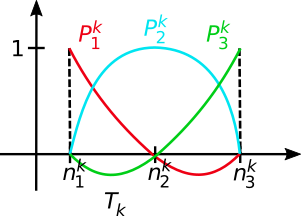

Ahora, la numeración global de los nodos no coincide con la de los vértices:

$n^k_j = n_{2(k-1)+j},\ j=1,2,3,\ k=1,\ldots,N_{el}$.

El número total de nodos es $N_{nod} = 2(N_{el}-1)+3 = 2N_{el}+1= 2N_{ver}-1$. El número total de elementos de $A_h$ no nulos es $3N_{nod}-2+2N_{el}$. En la siguiente figura, podemos ver el perfil de $A_h$ con elementos cuadráticos, $N_{el}=4$, $N_{ver}= 5$, $N_{nod}=9$. Los elementos no nulos en rojo representan la aportación $2N_{el}$.

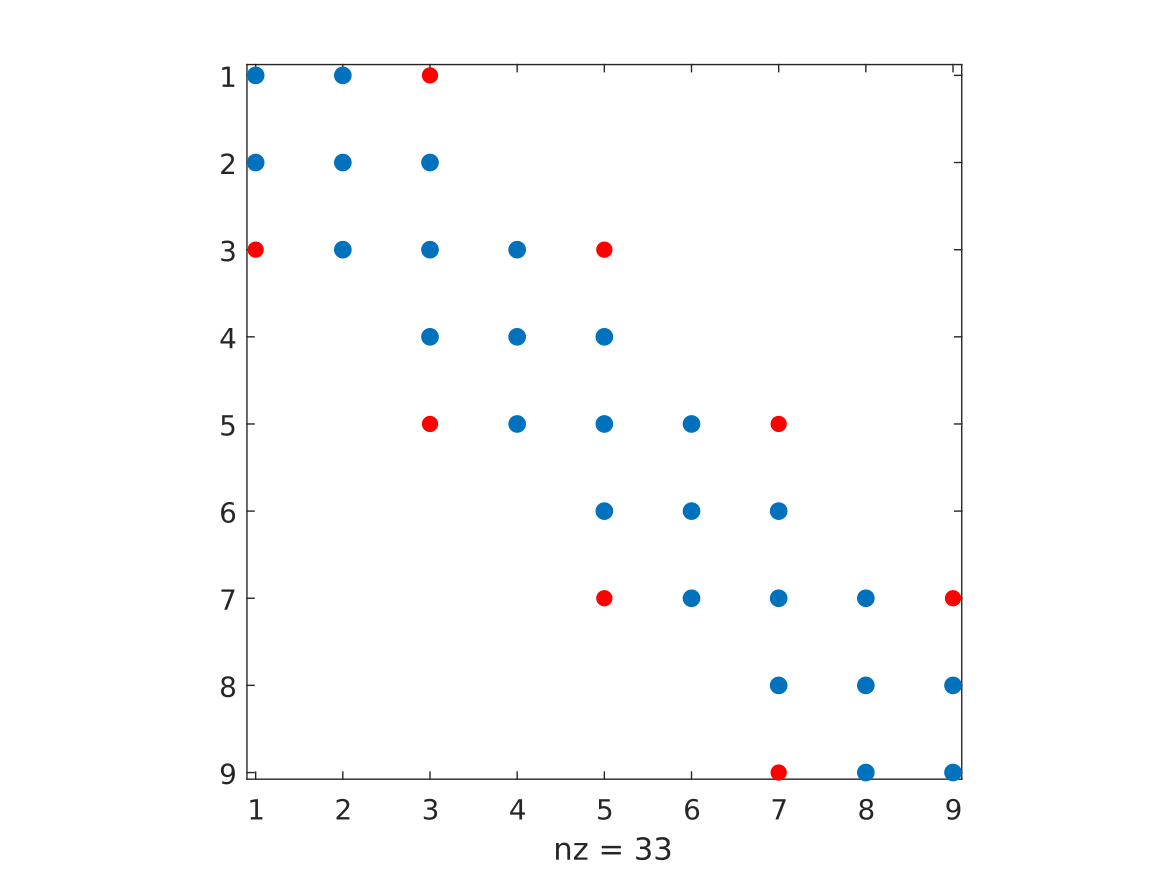

La matriz del problema discreto es una matriz banda con ancho 3 y, por tanto, es dispersa.

Finalmente, si $u\in H^3(a,b)$ es solución de (P), entonces la solución $u_h$ de (Ph) con elementos finitos de Lagrange cuadráticos verifica:


$$\|u^{(l)}- u_h^{(l)}\|_{L^2}\leq \mathcal(O)(h^{3-l}),\ l\in\{0,1,2\}.$$


### Implementación del método

La función [`ef`](matlab:open('./ef.m')) implementa el cálculo de la solución del problema discreto. Sus argumentos de entrada son:

- La estructura `m,` con la malla de elemenos finitos, compuesta de:

                  El grado del elemento finito, `m.deg`.

                  El número total de elementos, vértices y nodos, `m.nel`, `m.nver` y `m.nnod`.

                  Los vectores de abscisas de los vértices y nodos,  `m.xv` y `m.xn`.

                  En la práctica será necesario dividir el dominio en subdominios y evaluar las funciones dependiendo del subdominio. Para ello, la malla incorpora el vector de número de subdominio de cada elemento, `m.nsd`.

- La estructura `F` con cuatro funciones anónimas `p`, `q`, `r` y `f` que admiten como argumento dos escalares, una abscisa `x` y un número de subdominio `nsd` (la implementación del término para $q$ queda como ejercicio).

- La estructura `bc,` que define las condiciones de contorno:

                  si hay una condición Dirichlet en $x=a$: *y*(`bc.a`) = `bc.ua`; en otro caso:  -*y'*(`bc.a`) + `bc.ha` *y*(`bc.a`) = `bc.ga`.

                  si hay una condición Dirichlet en $x=b$: *y*(`bc.b`) = `bc.ub`; en otro caso:   *y'*(`bc.b`) + `bc.hb` *y*(`bc.b`) = `bc.gb`.

                  Como en este práctica no existe `blk_a`, `ua` sólo debe definirse para cuando la condición en $a$ es Dirichlet (y `ha`, `ga` sólo con una condición Robin.

- La estructura `qd,` que define la fórmula de cuadratura, compuesta el número de puntos de cuadratura, `qd.n` y los vectores de pesos y puntos de cuadratura `qd.w` y `qd.x`.

- La función ef tiene un argumento opcional para indicar una forma de bloqueo distinta la que tiene por defecto (por condensación). Este argumento opcional admite cualquiera de las funciones `block_subs` (bloqueo por sustitución) y `block_pivot` (bloqueo por pivote), definidas al final de la práctica.

### Ejercicio 6.1. Test académico

- **Ejecuta un test académico con elementos Lagrange lineales.**

Considera el problema:


$$\left\{\begin{array}{l}-u''-u=0,\\ u(0) = 3, \\ u(\frac{\pi}{2}) = 7.\end{array}\right.$$


Utiliza las fórmulas de cuadratura indicadas en `qd_formula` y construye la malla de $[0,\frac{\pi}{2}]$ compuesta por un único subdominio, mediante la función `mesher`.

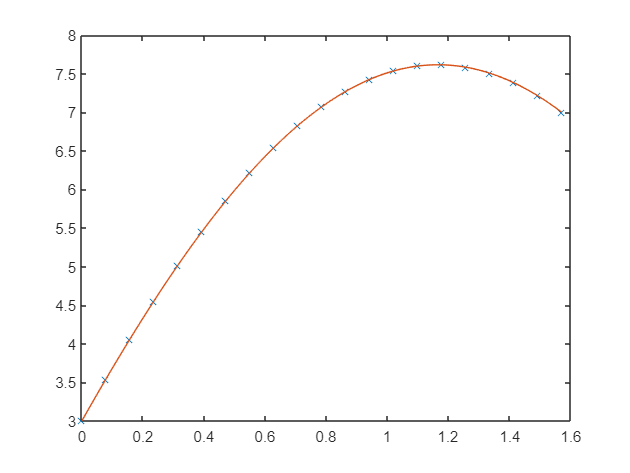

clf
m = 1;
F = struct('u', @(x) zeros(size(x)), ...
    'v', @(x)  -1.*ones(size(x)), ...
    'w', @(x) zeros(size(x)), ...
    'm', m);
bc = struct('blk_a', true, 'a', 0,    'ya', 3,  'ha', 1, ...
    'blk_b', true, 'b', pi/2, 'yb', 7 , 'hb', 1);

%h = 0.1
n = round(bc.b-bc.a)/0.1;
nl = struct('yk', ones(1,n+1), 'maxit', 400, 'tol', 1.e-6);
[x1, y1, k1] = dfn(F, bc, n, nl);

plot(x1,y1,'x'); hold on

clear sd %borra componentes adicionales (futuras) al volver a este ejercicio
sd(1) = struct('a', 0, 'b', pi/2, 'n', 150, 'nsd', 1);
%malla
m = mesher(sd, 2);
%condiciones de contorno
bc = struct('a', sd(  1).a, 'ua', 3, ...
    'b', sd(end).b, 'ub', 7);
%EDO
F = struct('p', @(x, nsd)  1, ...
    'q', @(x, nsd)  0, ...
    'r', @(x, nsd) -1, ...
    'f', @(x, nsd)  0);
%formulas de cuadratura
qd = qd_formula;
%solucion aproximada
uh = ef(F, m, bc, qd.gauss2p);
plot(m.xn,uh)

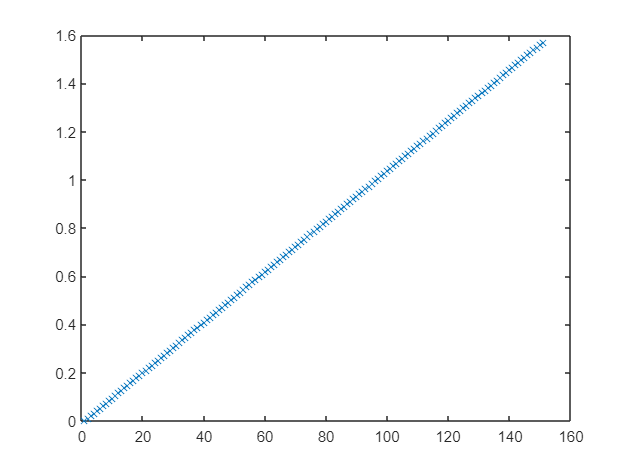

clf
% Densidad del mallado.
plot(1:1:length(m.xv),m.xv,'x')

- **Calcula la solución exacta del problema fuerte, su formulación débil y que se cumplen las condiciones del teorema de Lax-Milgram.**

La familia de soluciones de la EDO $u''=-u$ es $A\cos(x)+B\sin(x)$. Particularizando para las condiciones Dirichlet se obtiene la solución $u(x) = 3\cos(x) + 7\sin(x)$.

Observa que, aunque $u_h\notin V_{h,0}$ la función $\tilde{u} = u-3\in V_{h,0}$ y verifica el problema el problema:

$a(\tilde{u},v) = a(u-3,v) = L(v)-\int 3r\, v, \ v\in V_{h,0}$.

Como $r$ es una función continua, $\tilde{u}$ sí verifica las condiciones del teorema de Lax-Milgram. Luego existe una única solución $\tilde{u}$ de este problema y, por tanto, una única solución $u$ del problema original.

- **Para el error absoluto, calcula la norma **$L^2(a,b)$**y el orden de convergencia experimental para la solución.**

Utiliza una adaptación de las funciones `norma2` y `orden` implementadas en la práctica 2.

sol = @(x) 3*cos(x) + 7*sin(x);
disp(['Norma L2  discreta del error absoluto: ' num2str(norma2(m.xn, uh, sol))])

Norma L2  discreta del error absoluto: 2.4827e-10


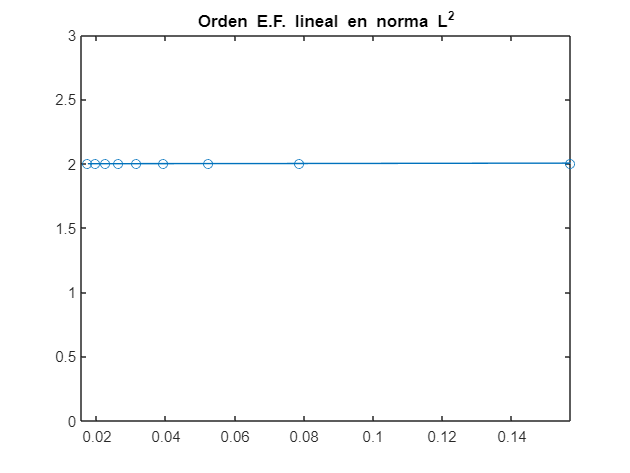

orden(F, 10:10:100, sd, 1, bc, qd.trapecio, sol, @norma2, 'Orden E.F. lineal en norma L^2', 0, 3);

**Observación para la clase:** 

Hasta $n= 100$, el error de redondeo de la máquina es pequeño respecto del error del algoritmo, por lo que es posible observar el orden de convergencia para E.F. cuadráticos usando fórmulas de cuadratura exactas en $\mathcal{P}^6$ descritas, por ejemplo, en [Zienkiewicz](https://iacobus.usc.es/record=b1734436~S1*gag). 

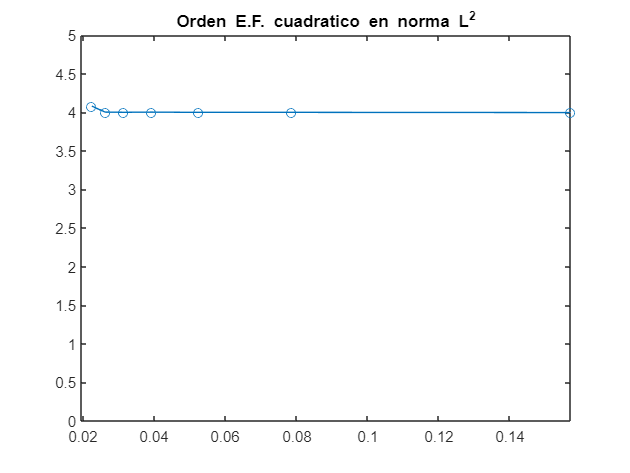

n =  10:10:80;
err = orden(F, n, sd, 2, bc, qd.gauss4p, sol, @norma2, 'Orden E.F. cuadratico en norma L^2', 0, 5);

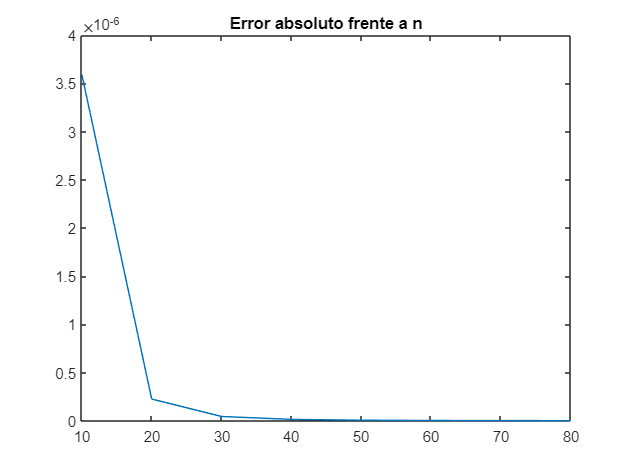

plot(n, err); title('Error absoluto frente a n')

Para valores de $n$ mayores, el error de redondeo empieza a ser del mismo orden que `epsilon` [de la máquina], por lo que no se puede observar el orden experimentalmente, aunque el error siga disminuyendo. El valor umbral de $n$ depende de cada problema.

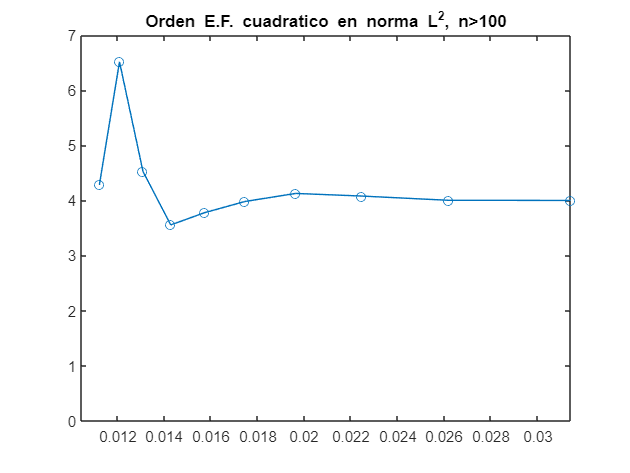

n =  50:10:150;
err = orden(F, n, sd, 2, bc, qd.gauss4p, sol, @norma2, 'Orden E.F. cuadratico en norma L^2, n>100', 0, 7);

- **Para la derivada, calcula el error absoluto en la norma **$L^2(a,b)$ **de la derivada y el orden de convergencia experimental.**

Utiliza la función `seminormaH1`, una adaptación de la función `normaH1` implementada en la práctica 3, que calcula $\|u'-u'_h\|_{L^2}$.

disp(['Norma L2 discreta del error absoluto de la derivada: ' num2str(seminormaH1(m.xn, uh, sol))])

Norma L2 discreta del error absoluto de la derivada: 2.2502e-05


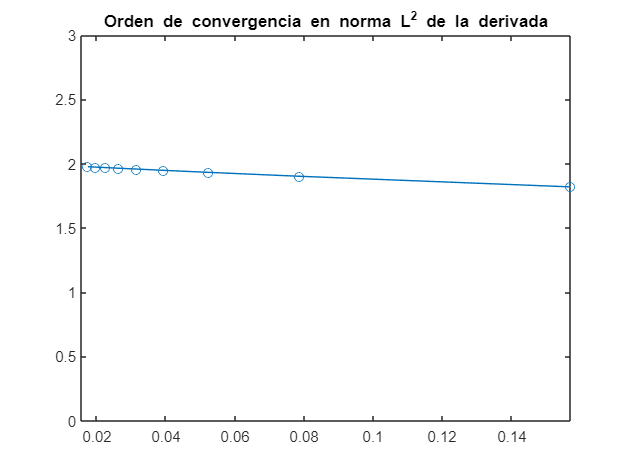

orden(F, 10:10:100, sd, 1, bc, qd.gauss2p, sol, @seminormaH1, 'Orden de convergencia en norma L^2 de la derivada', 0, 3);

**Observación para la clase:** Ver que se obtiene orden 2 para E.F. cuadráticos (en este caso, $n$ se puede tomar mayor que 100).

### Ejercicio 6.2. Test académico con término en $q$

- **Ejecuta un test académico con término en **$q$**. Implementa previamente este témino en **[ef.m](matlab:open('./ef.m'))**.**

Considera el problema:


$$\left\{\begin{array}{ll}-u''(t) +xu'+(1-x)u = -x^3+x^2+4x-2,\\
u(0) = 0,\\
u'(1)+u(1)=7.
\end{array}$$


clear sd
sd(1) = struct('a', 0, 'b', 1, 'n', 100, 'nsd', 1);
m = mesher(sd, 1);
bc = struct('a', sd(  1).a, 'ua',   0, ...
    'b', sd(end).b, 'hb',   1, 'gb', 7);
F = struct('p', @(x, nsd)    1, ...
    'q', @(x, nsd)    x, ...
    'r', @(x, nsd)  1-x, ...
    'f', @(x, nsd) -x^3+x^2+4*x-2);
qd = qd_formula;
uh = ef(F, m, bc, qd.gauss2p)

uh =          0    0.0201    0.0404    0.0609    0.0816    0.1025    0.1236    0.1449    0.1664    0.1881    0.2100    0.2321    0.2544    0.2769    0.2996    0.3225    0.3456    0.3689    0.3924    0.4161    0.4400    0.4641    0.4884    0.5129    0.5376    0.5625    0.5876    0.6129    0.6384    0.6641    0.6900    0.7161    0.7424    0.7689    0.7956    0.8225    0.8496    0.8769    0.9044    0.9321    0.9600    0.9881    1.0164    1.0449    1.0736    1.1025    1.1316    1.1609    1.1904    1.2201


- **Representa grá**`fi`**camente la solución exacta y la aproximada.**

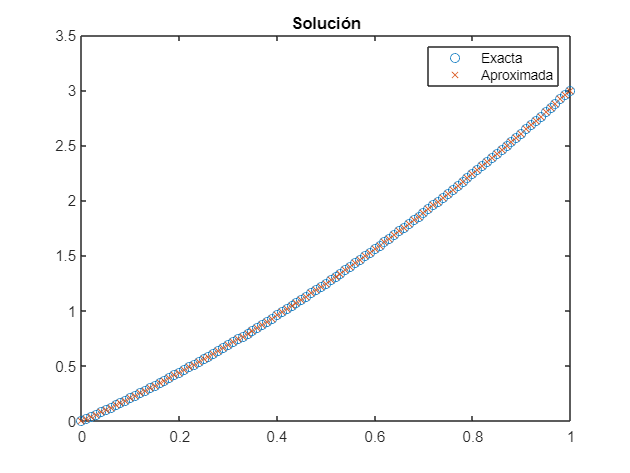

syms u(x)
% p=1 así que estamos en un caso muy muy particular
eqn = -F.p(x)*diff(u,x,2) + F.q(x)*diff(u,x) + F.r(x)*u == F.f(x);
Du = diff(u,x);
sol = matlabFunction(dsolve(eqn, [u(bc.a)==bc.ua, Du(bc.b)+bc.hb*u(bc.b)==bc.gb]));
plot(m.xn, sol(m.xn),'o', m.xn, uh,'x')
title('Solución')
legend('Exacta', 'Aproximada')

### Ejercicio 6.3. Test académico con una formulación alternativa

#### Formulación alternativa

Cuando la formulación fuerte es del tipo:

$-pu''+qu'+ru=f$,

su formulación débil es:


$$-\int pu''v+\int qu'v+\int ruv=\int fv$$


Usando la identidad de Green $\int (pu'v)' =$ $\int (pu')'v + \int pu'v' = \int p'u'v + \int pu''v + \int pu'v' = [pu'v]_a^b$  obtenemos:


$$\int pu'v'-[pu'v]_a^b+\int (p'+q)u'v+\int ruv=\int fv$$


Es decir, esta formulación alternativa puede resolverse con un programa preparado para la formulación original, indicando $p'+q$ en el argumento destinado a $q$.

- **Ejecuta un test académico con una formulación alternativa.**

Considera el problema:


$$\left\{\begin{array}{ll}-x^2u''(t) -2xu'+(1-x)u = -x^3-7x^2-2x,\\
u(0) = 0,\\
u'(1)+u(1)=7.
\end{array}$$


Esta formulación puede resolverse con [`ef`](matlab:open('./ef.m')), pasando $p'+q= 2x-2x= 0$ en el argumento destinado a $q$.

clear sd
sd(1) = struct('a', 0, 'b', 1, 'n', 100, 'nsd', 1);
m = mesher(sd, 1);
bc = struct('a', sd(  1).a, 'ua', 0, ...
    'b', sd(end).b, 'hb', 1, 'gb', 7);
F = struct('p', @(x, nsd)  x^2, ...
    'q', @(x, nsd)    0, ...
    'r', @(x, nsd)  1-x, ...
    'f', @(x, nsd) -x^3-7*x^2-2*x);
qd = qd_formula;
uh = ef(F, m, bc, qd.gauss2p)

uh =          0    0.0201    0.0404    0.0609    0.0816    0.1025    0.1236    0.1449    0.1664    0.1881    0.2100    0.2321    0.2544    0.2769    0.2996    0.3225    0.3456    0.3689    0.3924    0.4161    0.4400    0.4641    0.4884    0.5129    0.5376    0.5625    0.5876    0.6129    0.6384    0.6641    0.6900    0.7161    0.7424    0.7689    0.7956    0.8225    0.8496    0.8769    0.9044    0.9321    0.9600    0.9881    1.0164    1.0449    1.0736    1.1025    1.1316    1.1609    1.1904    1.2201


- **Representa grá**`fi`**camente la solución exacta y la aproximada.**

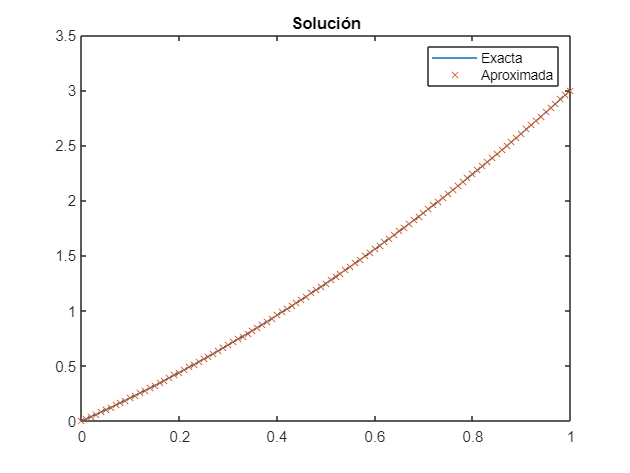

syms u(x)
eqn = -x^2*diff(u,x,2) - 2*x*diff(u,x) + F.r(x)*u == F.f(x);
Du = diff(u,x);
sol = matlabFunction(dsolve(eqn, [u(bc.a)==bc.ua, Du(bc.b)+bc.hb*u(bc.b)==bc.gb]));
plot(m.xn, sol(m.xn), m.xn, uh,'x')
title('Solución')
legend('Exacta', 'Aproximada')

- **Repite el cálculo del orden de convergencia para la función y su derivada.**

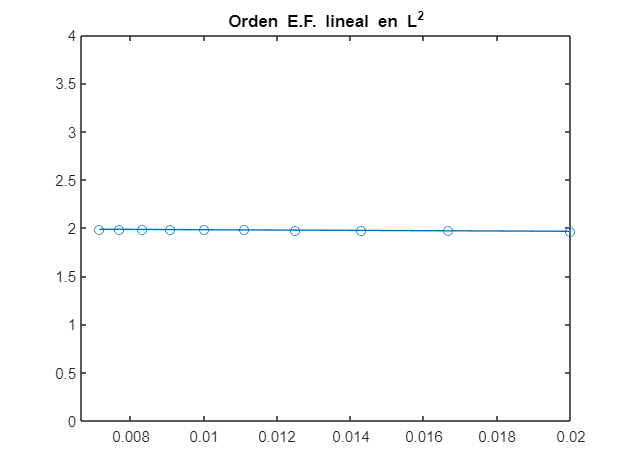

n =  50:10:150;
orden(F, n, sd, 1, bc, qd.gauss4p, sol, @norma2, 'Orden E.F. lineal en L^2', 0, 4);

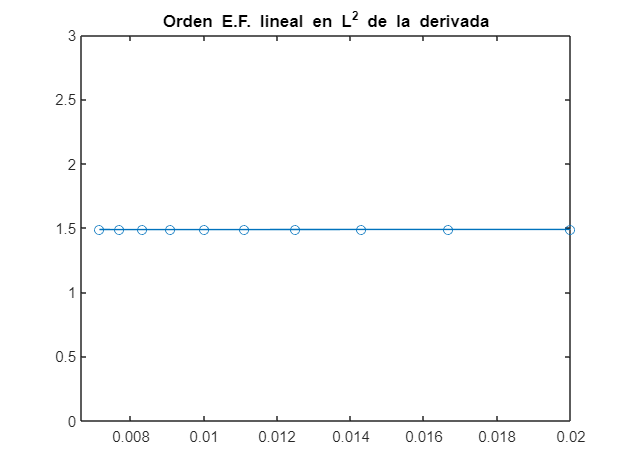

orden(F, n, sd, 1, bc, qd.gauss4p, sol, @seminormaH1, 'Orden E.F. lineal en L^2 de la derivada', 0, 3);

### Mecánica de sólidos elásticos

Consideramos un punto $\mathbf{p}$ en el dominio no deformado (o *material*) de un cuerpo, por ejemplo, una barra de sección $A$ y longitud $L$. Al aplicar una fuerza, dicho punto se desplazará a una posición $\mathbf{x}(\mathbf{p},t)$ en el dominio deformado (o *espacial*). Es decir, ha sufrido un *desplazamiento* $\mathbf{u}(\mathbf{p},t) = \mathbf{x}(\mathbf{p},t)- \mathbf{p}$. 

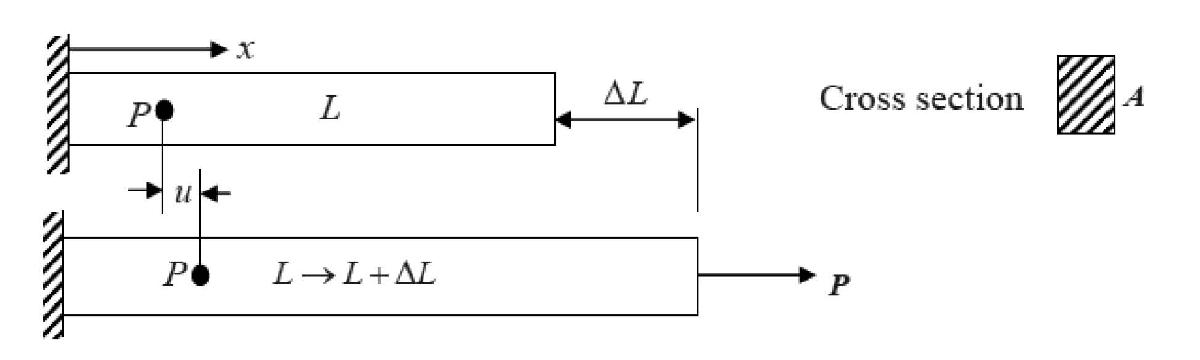

El tensor de tensiones de Cauchy define el estado de *tensión* o *esfuerzo *(fuerza por unidad de área) alrededor de un punto $\mathbf{x}$ del dominio espacial. Fijado un sistema de referencia, la tensión en $\mathbf{x}$ en la dirección normal al vector unitario $\mathbf{n}$ es $\sigma\,\mathbf{n}$, siendo $\sigma$ una matriz simétrica. 

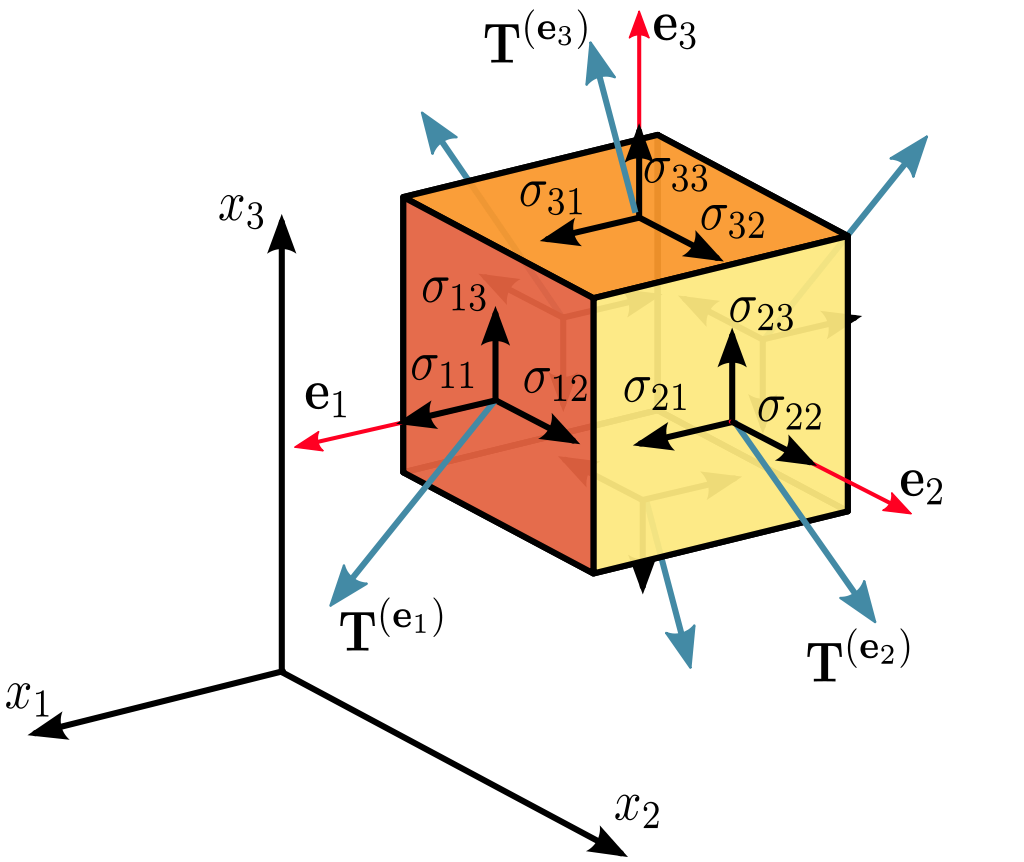

[Sanpaz, CC BY-SA 3.0](https://commons.wikimedia.org/w/index.php?curid=5668647)

En el rango elástico de un material, el módulo de Young $E$determina la relación entre la tensión y el gradiente del desplazamiento, $\nabla \mathbf{u}$. Si suponemos que todas las fuerzas actúan en la dirección $x$ el desplazamiento sólo tendrá componente $x$, $\mathbf{u}=u\,\mathbf{e}_x$ y el esfuerzo total normal a una sección de la barra es:


$$A\sigma\mathbf{e}_x = A\sigma_{xx} = AE\partial_xu$$


La ecuación de conservación del momento indica que, en un cuerpo en equilibrio, la resultante de todas las fuerzas o *cargas* aplicadas es cero:

$\text{div}\sigma +\mathbf{F} =0$. 

Suponemos que la única fuerza volúmica $\mathbf{F}$ es la gravedad, y que actúa en la dirección del eje $x$, $\mathbf{F}= \rho g\mathbf{e}_x$, siendo $\rho$ la densidad del cuerpo y $g$ la constante de la gravedad. La ecuación de conservación en la dirección $x$ queda: 


$$-\partial_x(A\sigma_{xx}) = -\partial_x(AE\partial_xu) = \rho g A$$


El lado izquierdo se domina *término de rigidez. *Para las condiciones de contorno, suponemos que la barra está encastrada en el extremo izquierdo, $u(0)=0$ y que la fuerza superficial en el extremo derecho es conocida, $AE\partial_xu(L) = P$. 

### Ejercicio 6.4. Elongación de una barra de acero

Considera el problema:


$$\left\{\begin{array}{l}
-\partial_x(AE\partial_xu) = \rho g A,\ x\in[0,L]\\
u(0) = 0,\\
AE\partial_xu(L) = P,
\end{array}$$


correspondiente al desplazamiento de una barra de acero de longitud $L=10\ \text{m}$ y de sección rectángular $A$ de altura 15 cm y anchura 20 cm. Suponemos que el eje de la barra sigue la dirección $x$ , las fuerzas actúan en dicha dirección y la fuerza superficial total en el extremo derecho es $P=25\ \text{N}$. La densidad del acero es $\rho = 7850\ \text{kg}/\text{m}^3$ y su módulo de Young es $E= 21\cdot10^{10}\ \text{N}/\text{m}^2$.

- **Resuelve el problema anterior** **mediante elementos finitos.** 

L = 10; A = 15e-2*20e-2; E = 21e10; rho = 7850; P = 25; g = 9.81;
clear sd
sd(1) = struct('a', 0, 'b', L, 'n', 150, 'nsd', 1);
m = mesher(sd, 1);
bc = struct('a', sd(  1).a, 'ua', 0, ...
    'b', sd(end).b, 'hb', 0, 'gb', P);
F = struct('p', @(x, nsd)  A*E, ...
    'q', @(x, nsd)  0, ...
    'r', @(x, nsd)  0, ...
    'f', @(x, nsd)  rho*g*A);
qd = qd_formula;

tic
for i=1:100

    uh = ef(F, m, bc, qd.gauss2p);
    k(i) = toc;
    media = sum(k)/length(k);
end
disp(['El tiempo medio de ejecución del algoritmo es ',num2str(media)])

El tiempo medio de ejecución del algoritmo es 0.44064


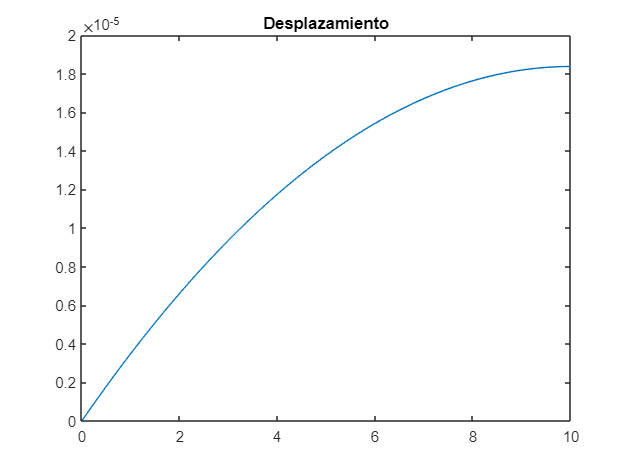

plot(m.xn, uh)
title('Desplazamiento')

- **Calcula los puntos de máxima compresión.**

Se habla de *compresión* allí donde el esfuerzo $AE\partial_xu$ es de signo negativo.

d1 = @(y,h) (y(3:end)-y(1:end-2))/(2*h); %aprox. primera derivada
sn = A*E*d1(uh, m.xn(2)-m.xn(1))         %suponemos un subdominio

sn = 1.0e+04 *

    2.2974    2.2820    2.2665    2.2511    2.2357    2.2203    2.2049    2.1895    2.1741    2.1587    2.1433    2.1279    2.1125    2.0971    2.0817    2.0663    2.0509    2.0355    2.0201    2.0047    1.9893    1.9739    1.9585    1.9431    1.9277    1.9123    1.8969    1.8815    1.8661    1.8507    1.8353    1.8199    1.8045    1.7891    1.7737    1.7583    1.7429    1.7275    1.7121    1.6967    1.6813    1.6659    1.6505    1.6351    1.6197    1.6043    1.5889    1.5735    1.5581    1.5427


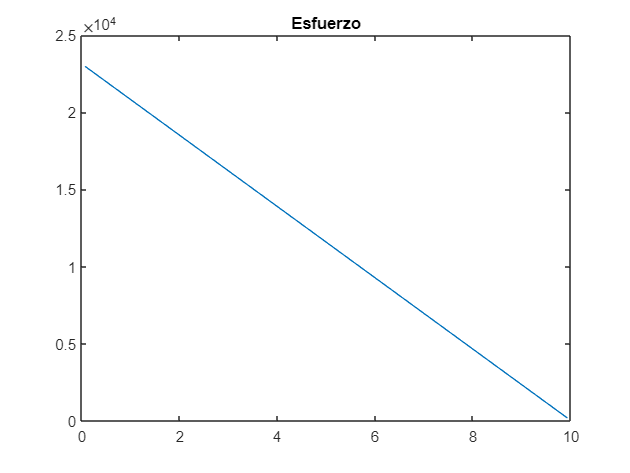

plot(m.xn(2:end-1), sn)
title('Esfuerzo')

[~,i] = min(sn);
disp(['Punto de mínima tensión en x = ' num2str(m.xn(i))])

Punto de mínima tensión en x = 9.8667


- **Prueba los dos otros tipos de bloqueo implementados en la práctica y calcula la norma **$L^2$ **discreta del error absoluto respecto de la solución aproximada con el método de condensación.**

Para utilizar los bloqueos por sustitución y pivote pasa como último argumento de `ef` el manejador de la función de bloqueo. Crea una función `norma2h` que permita calcular la norma $L^2$ discreta del error absoluto entre dos soluciones discretas.

norma2h = @(xh, uh1, uh2) sqrt(trapz(xh, (uh1 - uh2).^2)); % Norma L2 del error absoluto entre dos soluciones discretas
tic
us = ef(F, m, bc, qd.gauss2p, @block_subs);
toc

Elapsed time is 0.020538 seconds.


disp(['Norma L2 discreta del error absoluto entre bloqueo por condensación y sustitución: ' num2str(norma2h(m.xn, uh, us))])

Norma L2 discreta del error absoluto entre bloqueo por condensación y sustitución: 3.049e-18


tic
up = ef(F, m, bc, qd.gauss2p, @block_pivot);

A = eye;
disp(['El número de condicionamiento es: ' num2str(condest(A))])

El número de condicionamiento es: 1


toc

Elapsed time is 0.084624 seconds.


disp(['Norma L2 discreta del error absoluto entre bloqueo por condensación y pivote: ' num2str(norma2h(m.xn, uh, up))])

Norma L2 discreta del error absoluto entre bloqueo por condensación y pivote: 4.4534e-38


**Observación para la clase:** El bloqueo por pivote puede producir matrices con un mal condicionamiento. Para comprobarlo, basta con modificar `ef` para que los argumentos de salida sean `[u, A]`, y mostrar el número de condicionamiento con [`condest`](https://es.mathworks.com/help/matlab/ref/condest.html). Se ve que es del orden de 1e4 para sustitución y 1e34 para pivote.

### Transmisión del calor 1D

Supongamos una barra metálica del tipo y orientación descritos en el apartado anterior. La temperatura $T(x)$ a lo largo de una barra con sus paredes laterales aisladas verifica la ecuación del calor unidimensional:

$-\partial_x(k(x)\partial_x T(x)) = f(x)$,

donde $k(x)$ es la conductividad térmica (en $\text{W}/(\text{K}\,\text{m})$) y $f(x)$ la fuente volúmica de calor (en $\text{W}/\text{m}^3$).

Suponemos que la temperatura está fijada en el extremo izquierdo y cumple una condición de convección en el extremo derecho, es decir, el flujo de calor por dicho extremo es proporcional a la diferencia de temperatura con el exterior:

$k\partial_x T(L) = h(T_e-T(L))$.

Suponemos que la barra está compuesta de varios materiales, lo que obliga a definir dos subdominios y que la definición de $k$ depende del número de subdominio.

### Ejercicio 6.5. Transmisión del calor en una barra

Considera el problema:


$$\left\{\begin{array}{l}
-\partial_x(k(x,n_{sd})\partial_x\,T(x)) = f(x),\ x\in[0,L]\\
T(0) = T_0,\\
k\partial_x\,u(L) = h(T_e-T(L)),
\end{array}$$


correspondiente a la temperatura de una barra de acero en $[0,3]\ \text{m}$, de aluminio en $[3,5]\ \text{m}$ y de hierro en $[5,10]\ \text{m}$. La conductividades térmicas del acero, aluminio e hierro son 16.3, 237 y 75 $\text{W}/(\text{K}\,\text{m})$, respectivamente. Para las condiciones de contorno, toma  $T_0 = 50\ \text{ºC}$, $T_e = 20\ \text{ºC}$ y $h= 3\ \text{W}/(\text{K}\,\text{m}^2)$. La fuente volúmica de calor es $f(x) = \exp(5-x)\ \text{W}/\text{m}^3$.

- **Resuelve el problema anterior** **mediante elementos finitos.** 

L = 10;
clear sd
sd(1) = struct('a', 0, 'b', L, 'n', 150, 'nsd', 1);
m = mesher(sd, 1);
bc = struct('a', sd(  1).a, 'ua', 50, ...
    'b', sd(end).b, 'hb', 3, 'gb', 0);
F = struct('p', @(x, nsd)  (x<=3)*16.3 + (x>3 & x<5)*237 + (x>=5)*75, ...
    'q', @(x, nsd)  0, ...
    'r', @(x, nsd)  0, ...
    'f', @(x, nsd)  exp(5-x));
qd = qd_formula;

for i=1:8
    tic
    uh = ef(F, m, bc, qd.gauss2p);
    k(i) = toc;
    media = sum(k)/length(k);
end
disp(['El tiempo medio de ejecución del algoritmo es ',num2str(media)])

El tiempo medio de ejecución del algoritmo es 0.43577


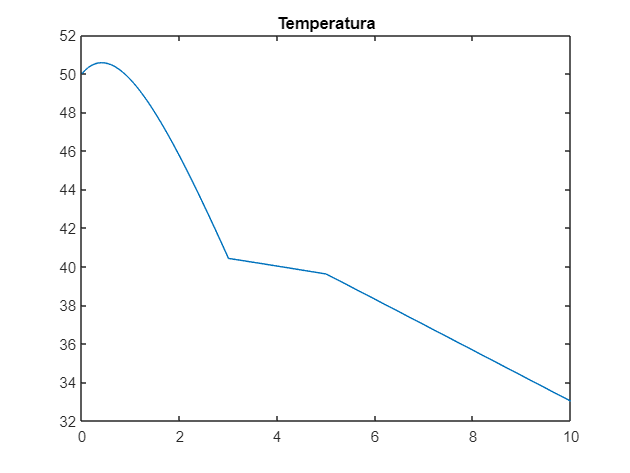

plot(m.xn, uh)
title('Temperatura')

- **Representa el flujo de calor en cada punto de la barra.**

Se debe representar la aproximación numérica de $k\partial_x T$ para los nodos centrales de cada subdominio.

d1 = @(y,h) (y(3:end)-y(1:end-2))/(2*h); %aprox. primera derivada
sn = @(x) F.p(x,1).*d1(uh, m.xn(2)-m.xn(1))

sn = function_handle with value:
    @(x)F.p(x,1).*d1(uh,m.xn(2)-m.xn(1))


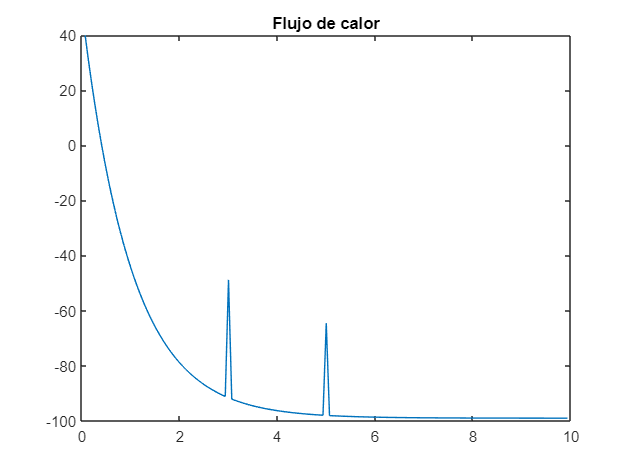

plot(m.xn(2:end-1), sn(m.xn(2:end-1)))
title('Flujo de calor')

### Ejercicio 6.6. Balance de masa de un reactor con decaimiento lineal en estado estacionario

Considera el problema:


$$\left\{\begin{array}{l}
-Dc''+U\,c'+\gamma c=0 ,\ x\in[0,L]\\
 -Dc'(0) + Uc(0)= Uc_{in},\\
c'(L) = 0.
\end{array}$$


- **Resuelve el problema anterior** **mediante elementos finitos.** 

Usa los siguientes datos: $L=10\, \text{m}$, $D=1\,\text{m}^2/\text{h}$, $U=1\,\text{m}/\text{h}$, $\gamma=0.2$, $c_{in}=100\,\text{mol}/\text{m}^3$. 

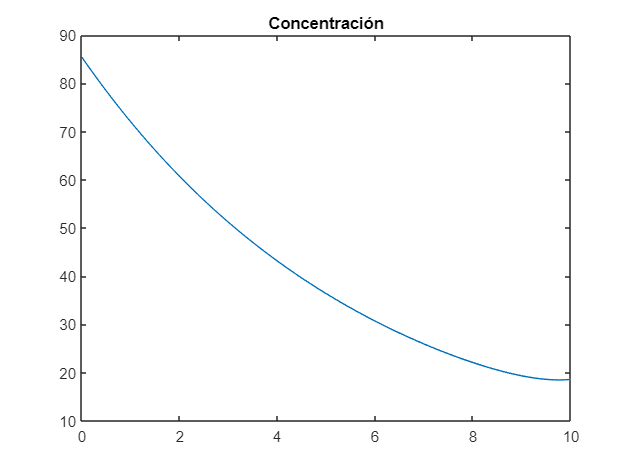

L = 10; D = 1; U = 1; gm = 0.2; cin = 100;
m=1;
clear sd
sd(1) = struct('a', 0, 'b', L, 'n', 150, 'nsd', 1);
m = mesher(sd, 1);
bc = struct('a', sd(  1).a, 'ga', U*cin/D, 'ha', U/D, ...
    'b', sd(end).b, 'gb', 1,       'hb', 0);

F  = struct('p', @(x,nsd)   D, ...
    'q', @(x,nsd) U, ...
    'r', @(x,nsd) gm, ...
    'f', @(x,nsd) 0);
qd = qd_formula;

uh = ef(F, m, bc, qd.gauss2p);
plot(m.xn, uh)
title('Concentración')

- **Calcula la solución exacta y la norma **$L^{2}(0,L)$** discreta del error absoluto.**

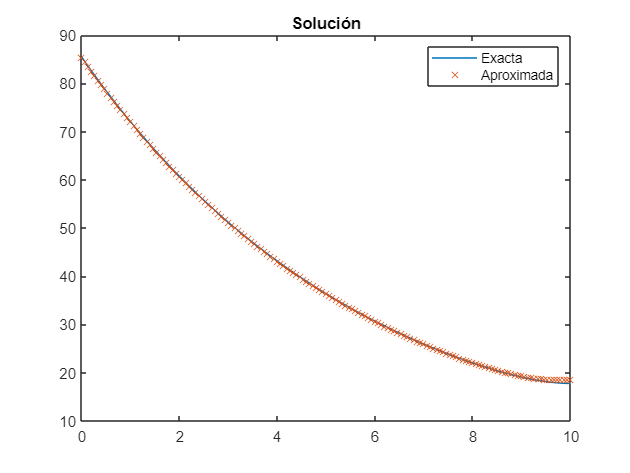

syms u(x)
eqn = -D*diff(u,x,2) + U*diff(u,x) + gm*u == 0;
Du = diff(u,x);
sol = matlabFunction(dsolve(eqn, [-Du(bc.a)+bc.ha*u(bc.a)==bc.ga, Du(bc.b)==0]));
plot(m.xn, sol(m.xn), m.xn, uh,'x')
title('Solución')
legend('Exacta', 'Aproximada')

### Algoritmo de iteración funcional

El paso $k$ del algoritmo de iteración funcional consiste en:

- Sea $u_k$ dado.

- Se calcula $u_{k+1}=\mathcal{F}(u_k)$, solución de $-pu'' +qu'+\tilde{r}u= f$ con las condiciones de contorno de ($\text{P}$) y $\tilde{r}(x) = r(x)u_k^{m-1}$*.*

- Si $\|u_{k+1}-u_k\|<\varepsilon$ hay convergencia; si no, sigue iterando.

### Implementación del algoritmo

La función [`efif`](matlab:open('./efif.m')) debe implementar el cálculo de la solución mediante el algoritmo anterior, usando el método de elementos finitos para resolver el problema lineal. Utiliza la función `dfif` de la práctica 3 como ejemplo.

### Ejercicio 6.6. Balance de masa de un reactor no lineal (iteración funcional) estacionario

Considera el problema:


$$\left\{\begin{array}{l}
-Dc''+U\,c'+\gamma c^m=0 ,\ x\in[0,L]\\
 -Dc'(0) = Uc_{in} - Uc(0),\\
c'(L) = 0.
\end{array}$$


- **Resuelve el problema anterior.** 

Usa los siguientes datos: $L=10\, \text{m}$, $D=1\,\text{m}^2/\text{h}$, $U=1\,\text{m}/\text{h}$, $\gamma=0.2$, $c_{in}=100\,\text{mol}/\text{m}^3$ y $m=2$. 

L = 10; D = 1; U = 1; gm = 0.2; cin = 100;
m = 2;

F  = struct('u', @(x)   zeros(size(x)), ...
    'v', @(x) gm*(ones(size(x))).^m/D, ...
    'w', @(x)  U*ones(size(x))/D, ...
    'm', 2);
bc = struct('blk_a', false, 'a', 0, 'ya', U*cin, 'ha', U, ...
    'blk_b', false, 'b', L, 'yb', 0,       'hb', 0);

n = (bc.b-bc.a)/0.1;
nl = struct('yk', ones(1,n+1), 'maxit', 400, 'tol', 1.e-6);
[xh, yh, kn] = dfif(F, bc, n, nl);
kn

kn = 2

clear sd
sd(1) = struct('a', 0, 'b', L, 'n', 150, 'nsd', 1);
m = mesher(sd, 1);
bc = struct('a', sd(  1).a, 'ha', U, 'ga', U*cin, ...
    'b', sd(end).b, 'hb', 0, 'gb', 0);
F = struct('p', @(x, nsd)  D, ...
    'q', @(x, nsd)  U, ...
    'r', @(x, nsd) gm, ...
    'f', @(x, nsd)  0, ...
    'm', 2);
qd = qd_formula;
nl = struct('uk', ones(size(m.xn)), 'maxit', 400, 'tol', 1.e-6);


[uh,k] = efif(F, m, bc, qd.gauss2p, nl);

- **Representa gráficamente las soluciones de elementos finitos y diferencias finitas**.

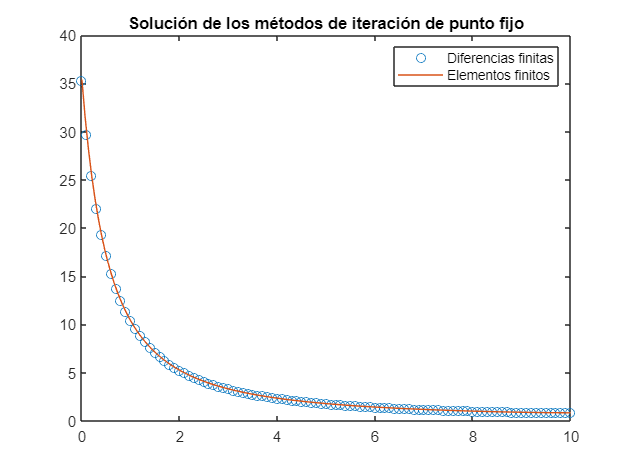

% Solucion
% suponemos (xh,yh) ya calculados del ejercicio anterior
plot(xh,yh,'o', m.xn,uh)
legend('Diferencias finitas', 'Elementos finitos')
title('Solución de los métodos de iteración de punto fijo')

### Algoritmo de Newton

Con la notación de la práctica 3, considera el operador $\mathcal{G}:y\in\mathcal{C}_{bc}^2([a,b])\mapsto r\in\mathcal{C}([a,b])$ definido por:

    $r(x)=\mathcal{G}(u)(x) = -(pu')' +q u' +ru^{m}-f$*.*

El paso $k$ del algoritmo de Newton consiste en:

- Sea $u_k\in\mathcal{C}_{bc}^2([a,b])$ dado.

- Se calcula $u_{k+1}$ como solución de $D\mathcal{G}(u_k)[u_{k+1}-u_k](x) = -\mathcal{G}(u_k)(x)$.

- Si $\|u_{k+1}-u_k\|<\varepsilon$ hay convergencia; si no, se sigue iterando.

El problema a resolver en el paso 2. es:

$-(p(u_{k+1}-u_k)')' +q(u_{k+1}-u_k)' + mru_k^{m-1}(u_{k+1}-u_k) = (pu_k')'-qu'_k-ru_k^m+f$,

o simplificadamente:

$-(pu'_{k+1})' +qu'_{k+1} + mru_k^{m-1}u_{k+1} =f + (m-1)ru^m_k$. 

Si definimos $\tilde{f} = f + (m-1)ru_k^m, \ \tilde{r} = mru_k^{m-1}$, entonces tenemos una EDO lineal que puede resolverse con elementos finitos.

### Implementación del algoritmo

La función [`efn`](matlab:open('./efn.m')) debe implementar el cálculo de la solución mediante el algoritmo anterior, usando el método de elementos finitos para resolver el problema lineal. Utiliza la función `dfn` de la práctica 3 como ejemplo.

### Ejercicio 6.7. Balance de masa de un reactor no lineal (Newton) estacionario

- **Resuelve el problema del ejercicio anterior utilizando el algoritmo de Newton.** 

%Solucion
L = 10; D = 1; U = 1; gm = 0.2; cin = 100;
m = 2;

F  = struct('u', @(x)   zeros(size(x)), ...
    'v', @(x) gm*(ones(size(x))).^m/D, ...
    'w', @(x)  U*ones(size(x))/D, ...
    'm', 2);
bc = struct('blk_a', false, 'a', 0, 'ya', U*cin, 'ha', U, ...
    'blk_b', false, 'b', L, 'yb', 0,       'hb', 0);

n = (bc.b-bc.a)/0.1;
nl = struct('yk', ones(1,n+1), 'maxit', 400, 'tol', 1.e-6);
[xh, yh, kn] = dfn(F, bc, n, nl);


clear sd
sd(1) = struct('a', 0, 'b', L, 'n', 150, 'nsd', 1);
m = mesher(sd, 1);
bc = struct('a', sd(  1).a, 'ha', U, 'ga', U*cin, ...
    'b', sd(end).b, 'hb', 0, 'gb', 0);
F = struct('p', @(x, nsd)  D, ...
    'q', @(x, nsd)  U, ...
    'r', @(x, nsd) gm, ...
    'f', @(x, nsd)  0, ...
    'm', 2);
qd = qd_formula;
nl = struct('uk', ones(size(m.xn)), 'maxit', 400, 'tol', 1.e-6);
[uh, ~] = efn(F, m, bc, qd.gauss2p, nl);

- **Representa gráficamente las soluciones de elementos finitos y diferencias finitas**.

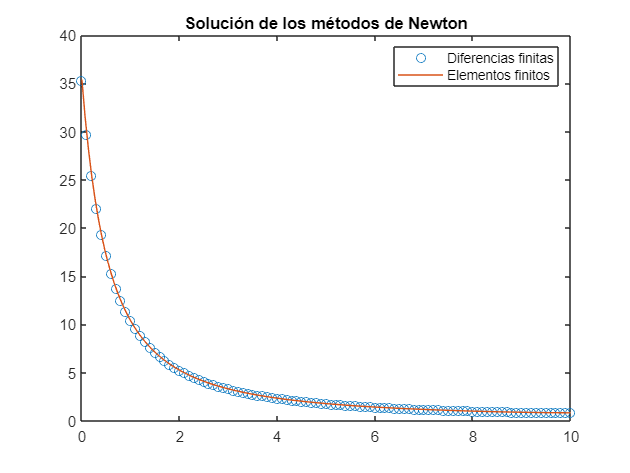

% Solucion
% suponemos (xh,yh) ya calculados del ejercicio anterior
plot(xh,yh,'o', m.xn,uh)
legend('Diferencias finitas', 'Elementos finitos')
title('Solución de los métodos de Newton')

### EDO evolutiva

Consideramos la EDO evolutiva:

$
l(x,t)\partial_t\,u(x,t) - \partial_x\left(p(x,t)\,\partial_x\,u(x,t)\right) + q(x,t)\,\partial_x\,u(x,t) + r(x,t)\,u(x,t)^m = f(x,t),\ x\in[a,b],\ t\in[t_0,t_f]
$,

con las notaciones, condiciones de contorno e iniciales indicadas en la práctica 4. Tomamos una discretización temporal $t^j=t_0+j\Delta t,\ j\in\{0,\ldots,n_t\}$. 

#### Caso lineal

En el caso lineal se obtiene:

$-\partial_x\left(p\partial_xu^j\right) + q\partial_x\,u^j + \left(r+\frac{l}{\Delta t}\right)u^j = f+ \frac{lu^{j-1}}{\Delta t}$.

Basta definir $\tilde{r} = r+\frac{l}{\Delta t}$, $\tilde{f} = f+\frac{lu^{j-1}}{\Delta t}$ caer en el caso lineal resuelto anteriormente por elementos finitos.

#### Iteración funcional

Se debe calcular $u_{k+1}=\mathcal{F}(u_k)$, solución de $-\partial_x(p\partial_xu) +qu'+\tilde{r}u= \tilde{f}$ con las condiciones de contorno dadas, $\tilde{r}(x) = r(x)u_k^{m-1}+\frac{l}{\Delta t}$ y $\tilde{f} = f+\frac{lu^{j-1}}{\Delta t}$*.*

#### Newton

El problema a resolver en el paso 2. es:

$-(p(u_{k+1}-u_k)')' +q(u_{k+1}-u_k)' + \left(mru_k^{m-1}+\frac{l}{\Delta t}\right)(u_{k+1}-u_k) = (pu_k')'-qu'_k-ru_k^m+f+\frac{lu^{j-1}}{\Delta t}-\frac{lu_k}{\Delta t}$,

o simplificadamente:

$-(pu'_{k+1})' +qu'_{k+1} + mru_k^{m-1}u_{k+1} =f + \frac{lu^{j-1}}{\Delta t}+\left(m-1+\frac{l}{\Delta t}\right)ru^m_k$. 

En este caso definimos  $\tilde{f} = f + \frac{lu^{j-1}}{\Delta t}+\left(m-1\right)ru^m_k$, $\tilde{r} = mru_k^{m-1}+\frac{l}{\Delta t}$

### Implementación del algoritmo

La función [`efnle`](matlab:open('./efnle.m')) debe implementar el cálculo de la solución mediante el algoritmo anterior, usando el método de elementos finitos para resolver el problema lineal. Utiliza la función efnle de la práctica 4 como ejemplo.

**Atención:** Las funciones defindas en `F` deben devolver un escalar (al contrario que en diferencias finitas). Allí donde sea necesario evaluar $u^{j-1}$ debe interpolarse en la coordenada $x$ dada, es decir, `interp1(m.xn, U(j-1,:), x)`.

### Ejercicio 6.8. Balance de masa de un reactor lineal evolutivo

Considera el problema del problema del balance de masa con decaimiento lineal.

- **Resuelve el problema lineal mediante elementos finitos.** 

Usa los siguientes datos: $L=10\, \text{m}$, $D=2\,\text{m}^2/\text{h}$, $U=2\,\text{m}/\text{h}$, $\gamma=0.2$, $c_{in}=100\,\text{mol}/\text{m}^3$, $l(x,t,n_{sd})=1$.  Representa la solución con [`contourf`](https://es.mathworks.com/help/matlab/ref/contourf.html) y compárala visualmente con la obtenida en el Ejercicio 4.2.

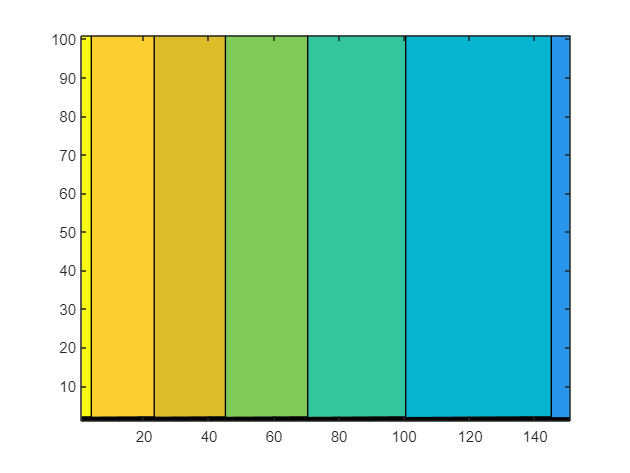

%Solucion
L = 10; D = 2; U = 2; gm = 0.2; cin = 100;
clear sd
sd(1) = struct('a', 0, 'b', L, 'n', 150, 'nsd', 1);
m = mesher(sd, 1);
bi = struct('a', sd(  1).a, 'ha', U, 'ga', @(t) U*cin, ...
    'b', sd(end).b, 'hb', 0, 'gb', @(t) 0, ...
    't0', 0, 'tf', 15,'nt',100 , 'u0', zeros(size(m.xn)));
F = struct('l', @(x, t)  1, ...
    'p', @(x, t)  D, ...
    'q', @(x, t)  U, ...
    'r', @(x, t) gm, ...
    'f', @(x, t)  0, ...
    'm', 2);
qd = qd_formula;
nl = struct('maxit', 400, 'tol', 1.e-6);

[th, Uh] = efenle_esquema(F, m, bi, qd.gauss2p, nl, @ef, @block_subs);
contourf(Uh)

### Ejercicio 6.9. Balance de masa de un reactor no lineal (iteración funcional) evolutivo

Considera el problema del problema del balance de masa con decaimiento no lineal.

- **Resuelve el problema no lineal con **$m=2$** usando el algoritmo de iteración funcional.**

Usa los mismos datos que en el Ejercicio 6.7.  Representa la solución con [`contourf`](https://es.mathworks.com/help/matlab/ref/contourf.html). 

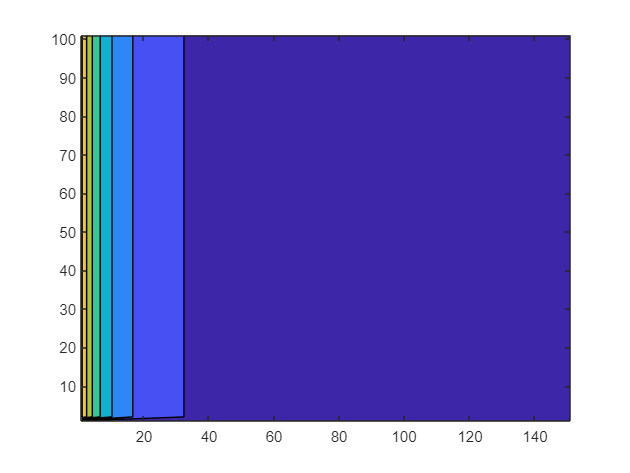

%Solucion
L = 10; D = 1; U = 1; gm = 0.2; cin = 100;
clear sd
sd(1) = struct('a', 0, 'b', L, 'n', 150, 'nsd', 1);
m = mesher(sd, 1);
bi = struct('a', sd(  1).a, 'ha', U, 'ga', @(t) U*cin, ...
    'b', sd(end).b, 'hb', 0, 'gb', @(t) 0, ...
    't0', 0, 'tf', 15,'nt',100 , 'u0', zeros(size(m.xn)));
F = struct('l', @(x, t)  1, ...
    'p', @(x, t)  D, ...
    'q', @(x, t)  U, ...
    'r', @(x, t) gm, ...
    'f', @(x, t)  0, ...
    'm', 2);
qd = qd_formula;
nl = struct('maxit', 400, 'tol', 1.e-6);


[th, Uh] = efenle_esquema(F, m, bi, qd.gauss2p, nl, @efif, @block_subs);
contourf(Uh)

### Ejercicio 6.10. Balance de masa de un reactor no lineal (Newton) evolutivo

Considera el problema del problema del balance de masa con decaimiento no lineal.

- **Resuelve el problema no lineal con **$m=2$ **usando el algoritmo de Newton.**

Usa los mismos datos que en el Ejercicio 6.7.  Representa la solución con [`contourf`](https://es.mathworks.com/help/matlab/ref/contourf.html). 

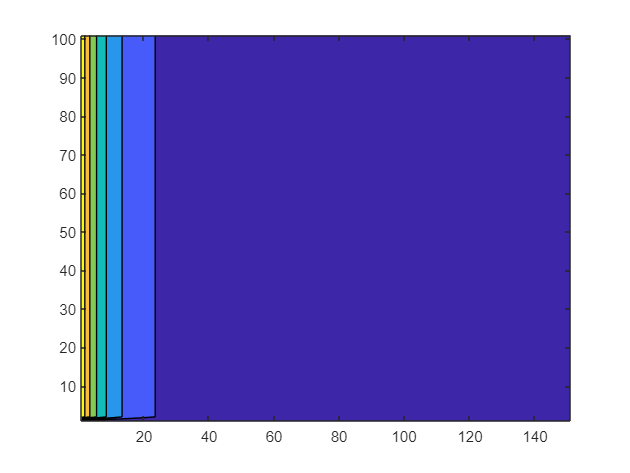

%Solucion
L = 10; D = 1; U = 1; gm = 0.2; cin = 100;
clear sd
sd(1) = struct('a', 0, 'b', L, 'n', 150, 'nsd', 1);
m = mesher(sd, 1);
bi = struct('a', sd(  1).a, 'ha', U, 'ga', @(t) U*cin, ...
    'b', sd(end).b, 'hb', 0, 'gb', @(t) 0, ...
    't0', 0, 'tf', 15,'nt',100 , 'u0', zeros(size(m.xn)));
F = struct('l', @(x, t)  1, ...
    'p', @(x, t)  D, ...
    'q', @(x, t)  U, ...
    'r', @(x, t) gm, ...
    'f', @(x, t)  0, ...
    'm', 2);
qd = qd_formula;
nl = struct('maxit', 400, 'tol', 1.e-6);


[th, Uh] = efenle_esquema(F, m, bi, qd.gauss2p, nl, @efn, @block_subs);
contourf(Uh)

## **Anexo. Funciones utilizadas en esta práctica**

En Matlab, las funciones utilizadas en un *script*, van al final de éste.

function m = mesher(sd, deg)
%MESHSER   Construccion de la malla de elementos finitos de grado M.DEG,
%    con M.NEL elementos, M.NVER vertices de coordenadas M.XV,
%    con M.NNOD nodos de coordenadas M.XN y numero de subdominio M.NSD
m.xv = [sd(1).a]; m.xn = m.xv; m.nsd = [];
for i = 1:length(sd)
    h     = (sd(i).b-sd(i).a)/sd(i).n;
    m.xv  = [m.xv,  sd(i).a + h*(1:sd(i).n)];
    m.xn  = [m.xn,  sd(i).a + h*(1:sd(i).n*deg)/deg];
    m.nsd = [m.nsd, sd(i).nsd*ones(1,sd(i).n)];
end
m.nver = length(m.xv);
m.nnod = length(m.xn);
m.nel  = length(m.nsd);
m.deg  = deg;
end

function [A, b] = block_subs(A, b, bc)
%BLOCK_SUBS   Bloqueo por sustitucion de la filas del sistema por:
%    A(1,1)     U(BC.A) = A(1,1)     BC.UA
%    A(end,end) U(BC.B) = A(end,end) BC.UB
if isfield(bc,'ua')
    b(1) = A(1,1)*bc.ua;
    A(1,2:end) = 0;
end
if isfield(bc,'ub')
    b(end) = A(end,end)*bc.ub;
    A(end,1:end-1) = 0;
end
end

function [A, b] = block_pivot(A, b, bc)
%BLOCK_SUBS   Bloqueo por cambio de pivote:
%    [1e30*A(1,1) A(1,2) ... A(1,end)] U = 1e30 A(1,1) BC.UA
%    [A(end,1) ... A(end,end-2) 1e30*A(end,end)] U = 1e30 A(end,end) BC.UB
if isfield(bc,'ua')
    b(1)   = 1e30*A(1,1)*bc.ua;
    A(1,1) = 1e30*A(1,1);
end
if isfield(bc,'ub')
    b(end)     = 1e30*A(end,end)*bc.ub;
    A(end,end) = 1e30*A(end,end);
end
end

function qd = qd_formula
%QD_FORMULA   Estructura para formulas de cuadratura
x1 = 0.339981043584856; w1 = 0.652145154862546;
x2 = 0.861136311594953; w2 = 0.347854845137454;
qd = struct('poncelet', struct('n', 1, 'w', [1],       'x', [0.5]), ...
    'trapecio', struct('n', 2, 'w', [0.5 0.5], 'x', [0 1]), ...
    'gauss2p',  struct('n', 2, 'w', [0.5 0.5], 'x', [(1-sqrt(1/3))/2 (1+sqrt(1/3))/2]), ...
    'gauss4p',  struct('n', 4, 'w', [w2 w1 w1 w2]/2, 'x', (1 + [-x2 -x1 x1 x2])/2)); %#ok<NBRAK>
end

function v = norma2(xh, yh, sol)
%NORMA2   Calculo de la norma L2 discreta del error absoluto.
v = sqrt(trapz(xh, (sol(xh) - yh).^2));
end

function v = seminormaH1(xh, yh, sol)
%NORMAH1   Calculo de la seminorma H1 discreta del error absoluto.
d1 = @(y,h) (y(3:end)-y(1:end-2))/(2*h); %aprox. primera derivada
syms x
dsol = matlabFunction(diff(sol(x), x)); %sol(x) es simbolica
v = sqrt( trapz(xh(2:end-1), (dsol(xh(2:end-1)) - d1(yh,xh(2)-xh(1))).^2) );
end

function err = orden(F, n, sd, deg, bc, qd, sol, norma, titulo, pmin, pmax)
%ORDEN   Orden experimental de convergencia del metodo.
h = (sd(end).b - sd(1).a)./n; %suponemos un solo subdominio
err = zeros(size(n));
for i = 1:length(n)
    for j = 1:length(sd), sd(j).n = n(i); end
    m = mesher(sd, deg);
    uh = ef(F, m, bc, qd);
    err(i) = norma(m.xn, uh, sol);
end
p = log(err(2:end)./err(1:end-1)) ./ log(h(2:end)./h(1:end-1));
plot(h(1:end-1),p,'o-')
axis([h(end) h(1) pmin pmax])
title(titulo)
end